close all
clear
clc

gamma=1.4

gamma = 1.4000


vx=@(x,y,z,t) computeSolution(x,y,gamma,'vx')

vx = function_handle with value:
    @(x,y,z,t)computeSolution(x,y,gamma,'vx')


vy=@(x,y,z,t) computeSolution(x,y,gamma,'vy')

vy = function_handle with value:
    @(x,y,z,t)computeSolution(x,y,gamma,'vy')


c=@(x,y,z,t)  computeSolution(x,y,gamma,'c')

c = function_handle with value:
    @(x,y,z,t)computeSolution(x,y,gamma,'c')



[x,y]=meshgrid(linspace(1e-6,1,101));

tic
M=sqrt(vx(x,y).^2+vy(x,y).^2)./c(x,y);
toc

Elapsed time is 7.745174 seconds.


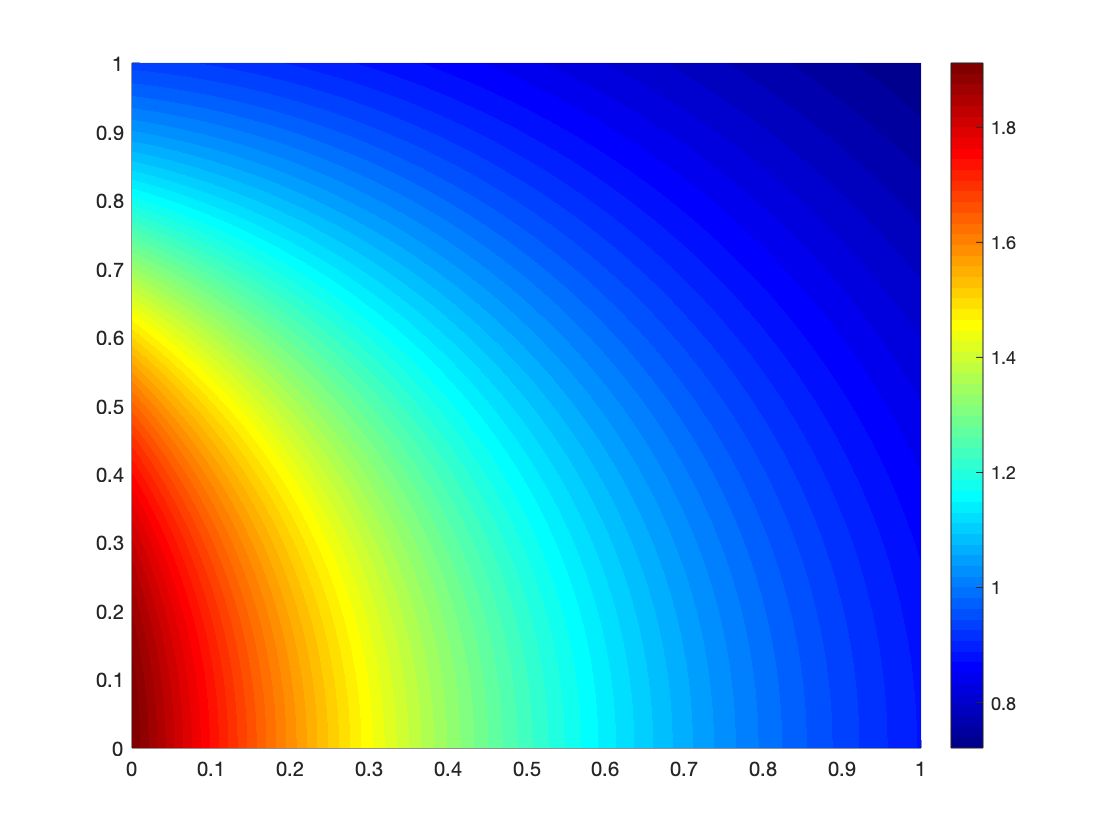


surf(x,y,M)
shading interp
colormap(jet(64))
colorbar
view(2)
xlim([0,1])
ylim([0,1])

function [sol]=computeSolution(x,y,gamma,var)
r=@(c) c.^(2/(gamma-1));
V=@(c) sqrt(2*(1-c.^2)/(gamma-1));
J=@(c) 1./c+1./(3*c.^3)+1./(5*c.^5)-1/2*log((1+c)./(1-c));
c=zeros(size(x));
for i=1:numel(x)
  f=@(c) (x(i)+J(c)/2)^2+y(i)^2-1/(4*r(c)^2*V(c)^4);
  c(i)=fzero(f,1/2);
end
r=r(c); V=V(c); J=J(c);
psi=sqrt(1./(2*V.^2)+r.*(x+J/2));
switch var
    case 'vx'
        sol=-sign(y).*V.^2.*psi;
    case 'vy'
        sol=V.*sqrt(1-(psi.*V).^2);
    case 'p'
        sol=1/gamma*c.^(2*gamma/(gamma-1));
    case 'c'
        sol=c;
end
end